%{
    This script plots each feature vs every other feature along with
    plotting R2 values which are with a specified range for a certain
    signal.

    We are looking for combinations of features that have some linear
    relationship (R2 value greater than ~0) but are not highly correlated (R2 value close to 1).

    A visual inspection is used to choose the features based on the
    previous statement. Those chosen features are then used to create a
    linear model.

    The signals are then normalized???
    A linear model is then computed using a combination of 2 signls
    The 3 parameter models are plotted
    The signals are then compared using the ??NORM?? metric
%}

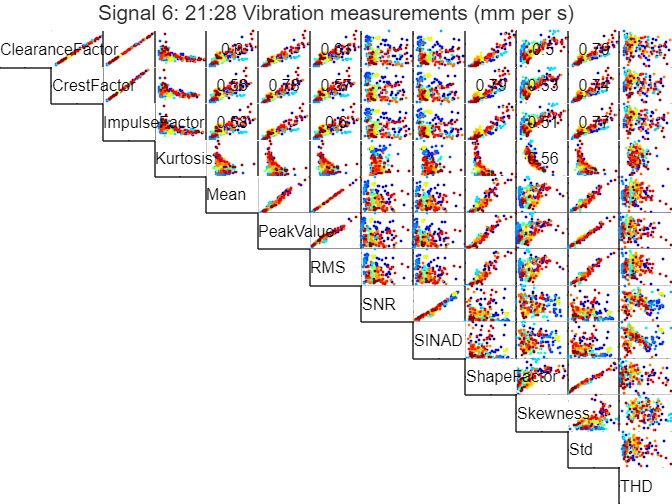

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
signalNum = 6; % 21:28 Vibration measurements (mm per s)
R2 = fnPlotFeatureVsFeature(Features, lowerR2, upperR2, signalNum, sensorNames, FeatureNames, signalNames_Time);

% Print the table of R2 values verse every other signal
disp(num2str(R2, '%.2f  '));

1.00  1.00  1.00  0.22  0.60  0.82  0.61  0.02  0.01  0.84  0.50  0.79  0.04
0.00  1.00  1.00  0.21  0.56  0.78  0.57  0.02  0.01  0.79  0.53  0.74  0.04
0.00  0.00  1.00  0.22  0.58  0.80  0.60  0.02  0.01  0.82  0.51  0.77  0.04
0.00  0.00  0.00  1.00  0.06  0.12  0.06  0.01  0.01  0.21  0.56  0.17  0.02
0.00  0.00  0.00  0.00  1.00  0.93  1.00  0.04  0.03  0.80  0.06  0.91  0.02
0.00  0.00  0.00  0.00  0.00  1.00  0.94  0.03  0.02  0.92  0.19  0.97  0.03
0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.04  0.03  0.82  0.06  0.92  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.96  0.02  0.00  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.01  0.00  0.01  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.25  0.97  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.19  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00

%%% Observations for Signal 6 %%%
% Looking at Feature 1 there are quite a few correlated features [4, 5, 6, 7, 10, 11, 12]
%
% Clearance, Crest and Impulse Factor all have R2 values of 1 so these are
% completely linear and thus we should only include one of these in the
% model.

% Another feature well correlated with the others is Feature 10 (Shape
% factor) [1, 2, 3, 4, 10, 11]. Features 1, 2 and 3 all have an R2 of 1 so
% we only need take one of these so another model combination set could be [1, 4, 11]

selectedFeature = 1;
selectedFeatureArray = [selectedFeature]; % Array of correlated features
for i = 1:numOfFeatures_Time + 1 - selectedFeature
    if R2(i,selectedFeature) > lowerR2 && R2(i,selectedFeature) < upperR2
        selectedFeatureArray = [selectedFeatureArray i];
    end
end
for i = selectedFeature + 1:numOfFeatures_Time
    if R2(selectedFeature,i) > lowerR2 && R2(selectedFeature,i) < upperR2
        selectedFeatureArray = [selectedFeatureArray i];
    end
end
selectedFeatureArray = sort(selectedFeatureArray);
numOfSelectedFeatures = size(selectedFeatureArray, 2);
selectedFeatureData = {numOfSelectedFeatures};

for i = 1:numOfSelectedFeatures
    selectedFeatureData{i} = Features.(signalNames_Time(signalNum) + FeatureNames(selectedFeatureArray(i)));
end

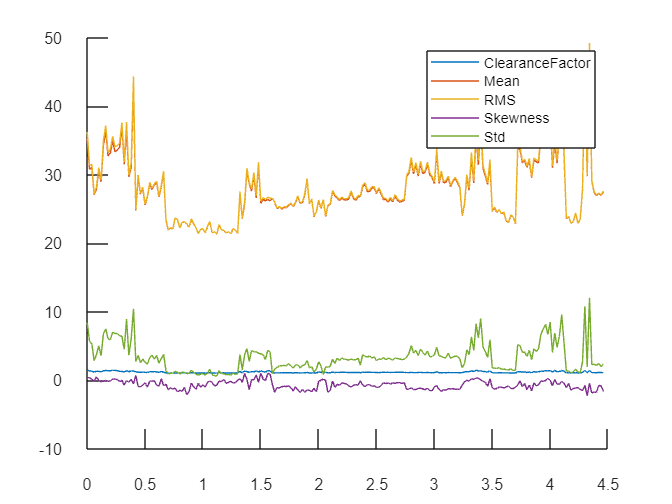

% Plot the identified signals for the Mean of each signal
n = size(selectedFeatureData{1}, 1); % Sample , 10
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
leg = {numOfSelectedFeatures};
for i = 1:numOfSelectedFeatures
    plot(t, selectedFeatureData{i});
    txtTemp = char(FeatureNames(selectedFeatureArray(i)));
    leg{i} = char(txtTemp);
end
legend(leg);

disp(selectedFeatureArray);

     1     5     7    11    12



% [ 1     4     5     6     7    10    11    12 ]
% Green (RMS 5) and Yellow (Mean 7) are almost identical so we can exclude
% one of those.
% When looking at the R2 table, Feature 1 (Clearance) has a high
% correlation with Feature 6 (0.82 Peak Value ), Feature 10 (0.84 Shape
% Factor) and Feature 12 (0.79 Std)
% So after eliminating 5, 6, 10 and 12 we're left with [ 1 4 7 11 ]

% X_signals = zeros(n, numOfSelectedFeatures);
% for i = 1:numOfSelectedFeatures
%     X_signals(:,i) = selectedFeatureData{i}; 
% end

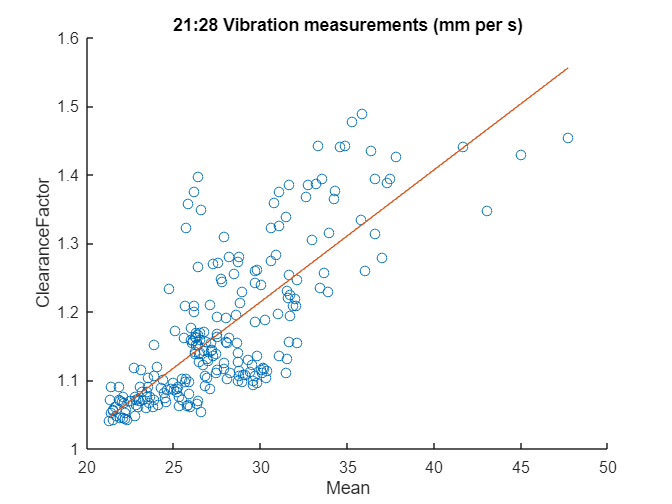

FIT = 36.48

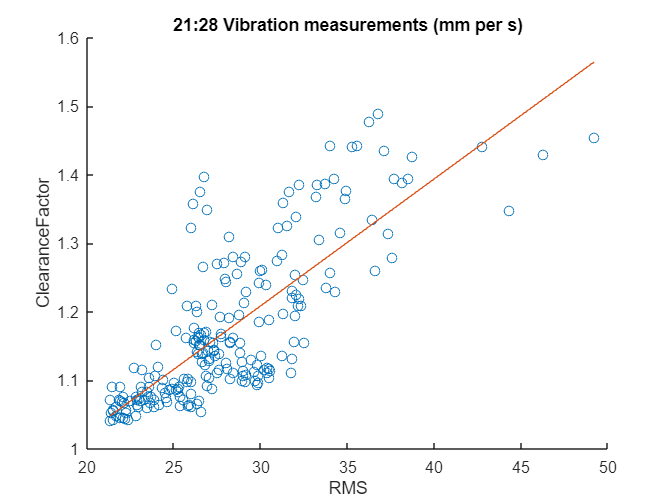

FIT = 37.57

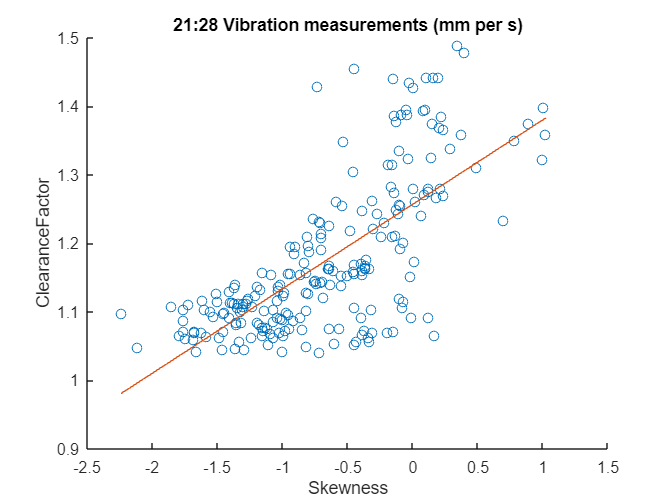

FIT = 29.45

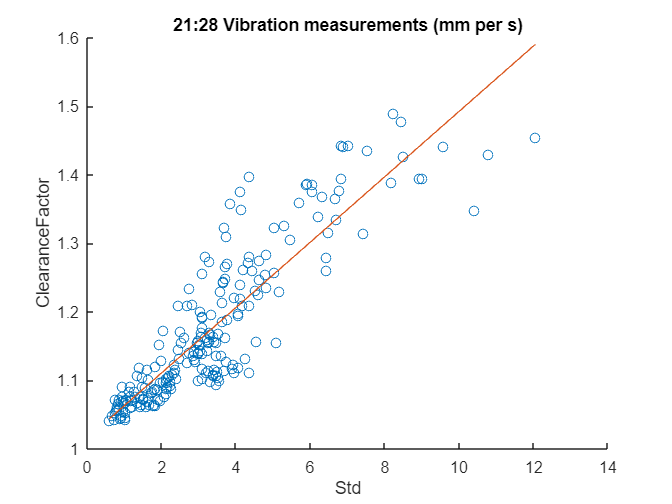

FIT = 53.87

for index = 1 : numOfSelectedFeatures
    if index ~= selectedFeature
        fnPlotModel(selectedFeatureData{selectedFeature}, selectedFeatureData{index}, sensorNames(signalNum), FeatureNames(selectedFeatureArray(selectedFeature)), FeatureNames(selectedFeatureArray(index)));
    end
end

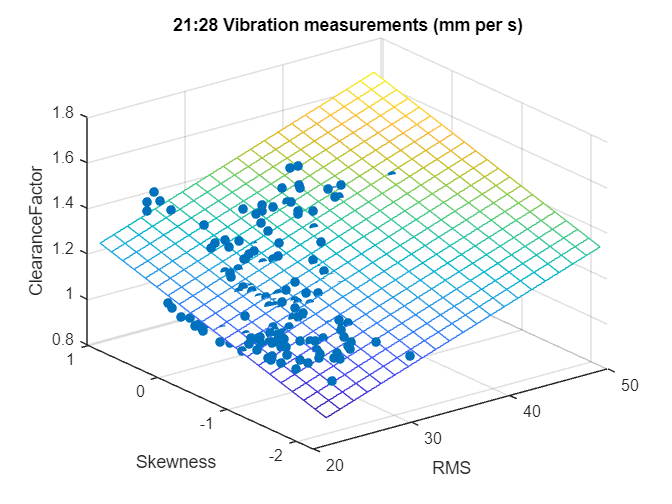

FIT = 66.806036

fnPlotModel3D( ...
    selectedFeatureData{1}, ...
    selectedFeatureData{3}, ...
    selectedFeatureData{4}, ...
    sensorNames(signalNum), ...
    FeatureNames(selectedFeatureArray(1)), ...
    FeatureNames(selectedFeatureArray(3)), ...
    FeatureNames(selectedFeatureArray(4)));

%    'nAIC': Normalized Akaike's Information Criterion (default)
%            nAIC = log(det(E'*E/N)) + 2d/N
%     'AIC': Akaike's Information Criterion (raw measure)
%            AIC = N*nAIC + N*(ny*log(2*pi) + 1)
AIC(1) = -2*(log(RSS)) + 2*k;

Unrecognized function or variable 'RSS'.

AIC2(1) = 2 * k + n * log (RSS / n); % Which is the better equation?

% An alternative formula for least squares regression type analyses 
% for normally distributed errors:
% https://www.statisticshowto.com/akaikes-information-criterion/
deltaAIC(1) = 2 * k + n * log(RSS);